# AMECH HW6

*Steven Henderson*

**1.**

**(c)**

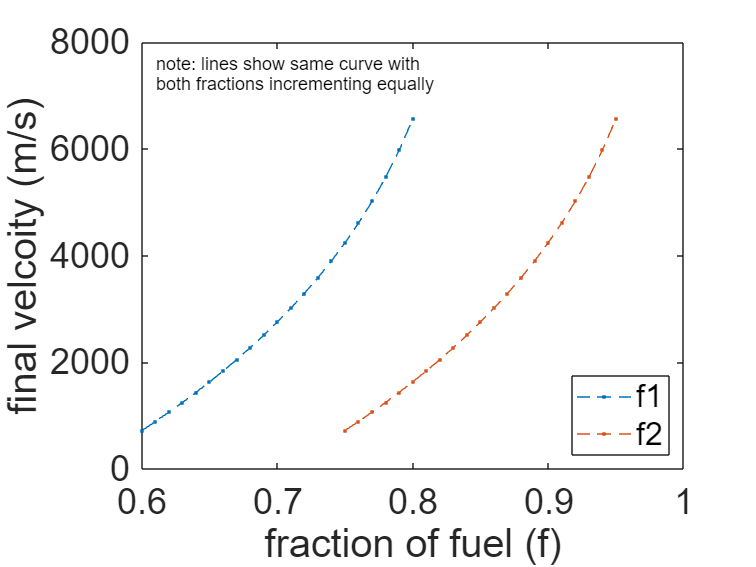

% Function to find v from homework v(t)
function v = find_v(T, u, mf, mi, vi)
    g = 9.8 ; % gravity m/2^2
    % find velocity from equation found in HW
    v = - g * T - u * log(mf ./ mi) + vi ;
end
f = [0.6:0.01:0.8; 0.75:0.01:0.95] ; % array of the fuel fractions needed
u = 3000 ; % exauhst speed (m/s)
T1 = 2.75 * 60 ; % burn time 1 (s)
T2 = 6.5 * 60 ; % burn time 2 (s)
m1 = 549 ; % mass of first stage piece (tons)
m2 = 120 ; % mass of second stage piece (tons)
mp = 0.375 ; % mass of paylaod (tons)
v1 = find_v(T1, u, m1 + m2 + mp - f(1, :).*m1, m1 + m2 + mp, 0) ; % finding the velocity after the first stage
v2 = find_v(T2, u, m2 + mp - m2.*f(2, :), m2 + mp, v1) ; % finding the velocity after the second stage
% Plot velocity vs. fraction
plot(f, v2, '--.')
set(gca, 'fontsize', 20)
xlabel('fraction of fuel (f)')
ylabel('final velcoity (m/s)')
legend('f1', 'f2', 'Location', 'southeast')
text(0.61, 7400, {'note: lines show same curve with', 'both fractions incrementing equally'})

**2.**

**(5) check pdf submission of written homework for equations used below**

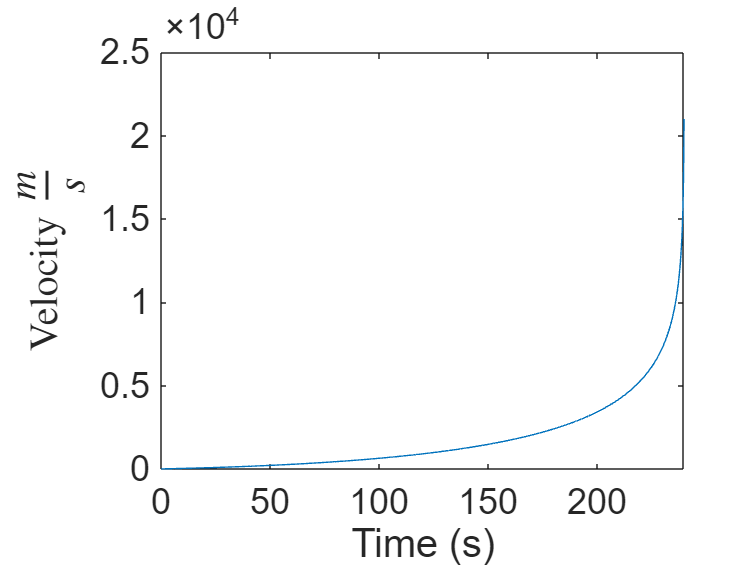

clear all
% find velocity and height based on t
a = 1/4 ; % burn constant alpha (1/min)
t = 0:0.1:4 *60; % time span (s)
u = 3000 ; % velocity of exhaust (m/s)
g = 9.8 ; % gravity m/s^2
v = - u * log(1 - a.*(t / 60)) - g*t ; % velocity at time t (m/s)
h = 0 + v.*t - 1/2*g.*t.^2 ; % height at time t (m)
% Plot data
plot(t, v)
xlabel('Time (s)')
ylabel('Velocity $\frac{m}{s}$', 'Interpreter','latex')
set(gca, 'fontsize', 20)

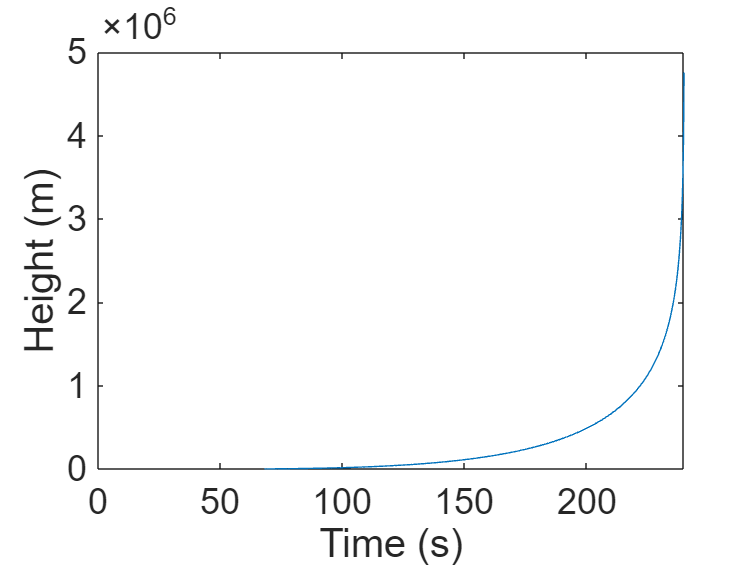

plot(t, h)
set(gca, 'fontsize', 20)
xlabel('Time (s)')
ylabel('Height (m)')
ylim([0, 5e6])

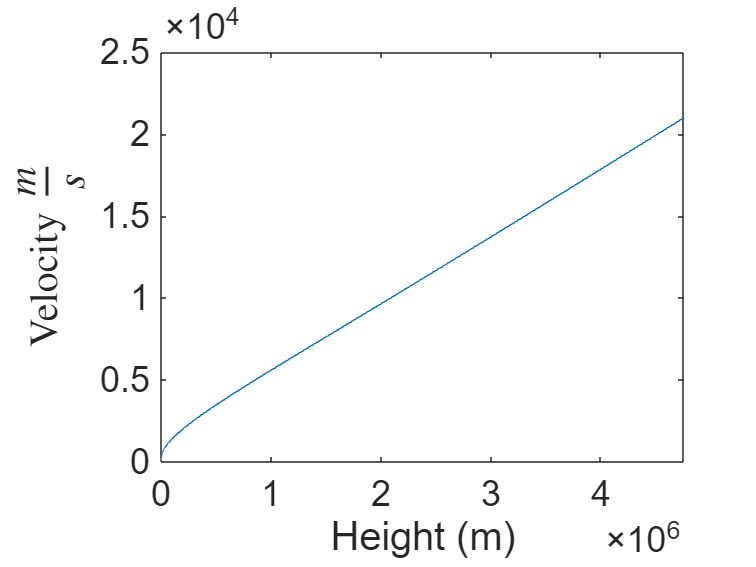

plot(h, v)
set(gca, 'fontsize', 20)
xlabel('Height (m)')
ylabel('Velocity $\frac{m}{s}$', 'Interpreter','latex')